% Procesamiento de la señal AIS - Decodificación

clear all;
fichero = 'senhal_depuracion_ais_384K.dat';  %Fichero a leer

flag = 1; %Los datos son complejos, no reales
tipo = 'float'; %Coma flotante de precisión simple (32 bits).
muestras = 'Inf'; %Se lee el fichero entero
orden = 'IQ'; 

X = lee_fichero_test(fichero, flag, tipo, muestras, orden);
%Una vez se tienen las muestras de la señal AIS pregrabada, el siguiente paso es re-muestrear la señal.
%Este proceso se realiza cuando se desea trabajar con una señal a una resolución más baja para simplificar el procesamiento o para que coincida con los requisitos del algoritmo.
%Aplicando el Teorema de Nyquist, al tener una señal compleja la frecuencia de muestreo debe de cumplir: fs = 1,28BW, siendo el ancho de banda de 75kHz para una señal AIS.
%fs = 1,28*BW = 1,28*75kHz = 96 kHz.

%Primer paso, cambiamos la frecuencia de muestreo de 384k a 96k
fs_nueva = 96000;
fs_original = 384000;

x_remuestreada = resample (X, 96000, 384000); %Remuestreamos la señal


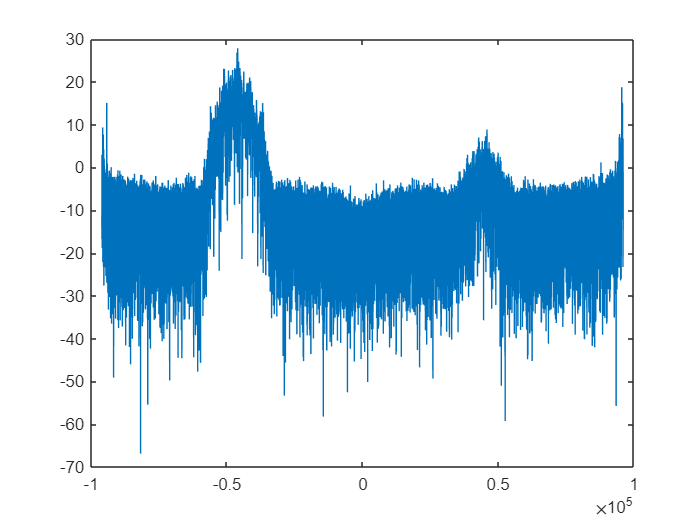

%Realizamos la fft de la señal
xfft = fft(x_remuestreada);
xf=  (20*log10(abs(xfft)));
%Dibujamos la fft 
vec = linspace (-fs_nueva,fs_nueva,length(x_remuestreada));
figure
plot(vec,(xf));

%Este resultado está bien, tiene sentido. Aqui podemos ver el pulso AIS.

%Detección gruesa mediante FFT
%Primero, nos interesa ver segmentos de la señal para encontrar el pulso,
%para ello se realiza un bucle de MxN

M = 960;
W = 15;
N = M/W;

%Enventanamos la señal, la ventana kaiser es la que mejor suaviza los
%aumentos en la señal
w = kaiser(M,6.9);
w = w*M/sum(w);

fres = 100;
frecs =  M/N*fres*(0:N-1);

indRuido = find(((frecs <= 15000) & (frecs >= 5000)) | ...
                 ((frecs >= mod(-15000,fs_nueva)) & (frecs <= mod(-5000,fs_nueva))));
indAisSup = find((frecs <= (25000+6125)) & (frecs >= (25000-6125)));
indAisInf = find((frecs >= mod(-(25000+6125),fs_nueva)) & (frecs <= mod(-(25000-6125),fs_nueva)));

K = length (indAisSup);

for ii = 1:floor((length(x_remuestreada)-M)/N+1)
    y = x_remuestreada((ii-1)*N+1:(ii-1)*N+M);
%     ffty = 20*log10(abs(fft(y)));
%     ffty_resultados(ii, :) = ffty;

    % La multiplicacion por la constante M/N*K sirve para igualar el nivel
    % medido en frecuencia con el nivel medido en el tiempo.  Desde el punto
    % de vista de la comparacion, es prescindible.  
    wffty = fft(wola(w.*y,N)/M);
    wffty_dB = 20*log10(abs(wffty));
    wffty_resultados(ii, :) = wffty_dB;

    noiseLevels = (abs(wffty(indRuido+1)).^2*M/N*K);
    noiseLevel(ii)  = mean(noiseLevels)+2.6*std(noiseLevels,1); 
    supAisLvl(ii) = mean(abs(wffty(indAisSup+1)).^2*M/N*K);
    infAisLvl(ii) = mean(abs(wffty(indAisInf+1)).^2*M/N*K);  
end %end for


% Mostrar todos los resultados. Se puede comentar para que no tarde tanto
% cada ejecución

ejeFrec = fs_nueva/N*((0:N-1)-N/2);

for ii = 1:size(wffty_resultados, 1)
    plot(ejeFrec, fftshift(wffty_resultados(ii, :))); % o muestra de otra forma, como prefieras
    title(['FFT Result ', num2str(ii)]);
    axis ([-fs_nueva/2, fs_nueva/2, -100, 0]);
    % Se puede ajustar la pausa de tiempo entre cada visualización si es necesario
    pause(0.001); % pausa para permitir la visualización
end %for

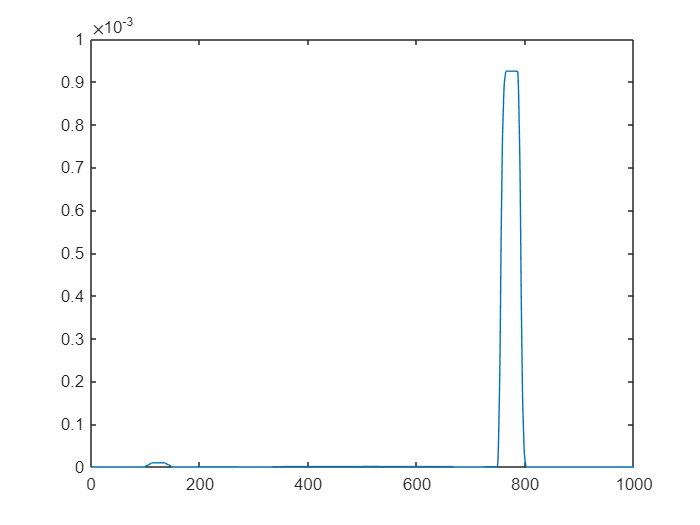

%Realizamos una media deslizante para quitar ruido
noiseLevelsinruido  = semavg(noiseLevel,501);
supAisLvlsinruido = semavg(supAisLvl(:),101);
infAisLvlsinruido = semavg(infAisLvl(:),101);

levels = vertcat (infAisLvlsinruido, noiseLevelsinruido, supAisLvlsinruido);
t = linspace ( 1, 1000, length (levels));
figure;
plot(t,levels);

Como vemos el ruido se nos quedo en una simple línea horizontal y la señal esta toda el canal superior en este caso

%Vemos en que canal esta la señal
flagAisInf = 0;
flagAisSup = 0;

mediainf = mean(infAisLvlsinruido);
mediasup = mean (supAisLvlsinruido);
if mediainf > mediasup
   detec = infAisLvlsinruido > noiseLevelsinruido *10^(3/10);
  flagAisInf = 1;
else 
    detec     = supAisLvlsinruido > noiseLevelsinruido*10^(3/10);
  flagAisSup = 1;  
end %if

pulso = gefh_detect(detec, detec); % Esta función localiza el primer uno y el ultimo

%Detección fina

OL = exp(1i*2*pi*25/96*(0:length(detec)-1)'); %Oscilador para centrar la señal

for ii = 1:length(pulso)
  iniInd = (pulso(ii).Bin_Inicial-1)*N+1;
  endInd   = (pulso(ii).Bin_Final-1)*N+1;
  if (endInd-iniInd+1 > fs_nueva*0.022)
       
    % Potencia de ruido estimada en el intervalo de tiempo de interes
    noisePow = mean(noiseLevelsinruido(pulso(ii).Bin_Inicial:pulso(ii).Bin_Final));

    % Adquirimos el tramo de se al de interes y pasamos este a 48KHz.  
    z = x_remuestreada(iniInd:endInd);
    oscilador = OL(mod((0:length(z)-1)',length(OL))+1);
    if flagAisSup == 1
      zy = z.*conj(oscilador);
    else
      zy = z.*(oscilador);
    end %if
    % Filtro de 25KHz de ancho de banda.
    s = load('lpf.mat');
    lpf = s.lpf;
    zfiltrada = filter(lpf,1,zy);
    zfinal = zfiltrada(1:2:end);
  %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    instPow = semavg(abs(zfinal).^2,31);
    detection = instPow > noisePow*10^(3/10);
    refinedPulses = [];
    refinedPulses = gefh_detect(detection,detection); 
  

for jj = 1:length(refinedPulses)
      iniInd = refinedPulses(jj).Bin_Inicial;
      endInd = refinedPulses(jj).Bin_Final;
      if (endInd-iniInd+1 > fs_nueva/2*0.022)
        
        % Aislamos el pulso actual
        instPowPulse = instPow(iniInd:endInd);
        z = zfinal(iniInd:endInd);
        
        % Obtenemos los instantes de comienzo y final del pulso calculando
        % la potencia media en el mismo y viendo los instantes de tiempo
        % donde esta cae por debajo de 3 dB en relacion al valor medio
        meanPow = mean(instPowPulse);
        indices = find(instPowPulse > meanPow*10^(-3/10));
        demodSignal = z(min(indices):max(indices));
        

        Samples  = (demodSignal);
        Fs = fs_nueva/2;
        SamplesPerSymbol = 5;
        
        validCRC = 0;
        Message = [];
        
        syncCalc = syncGen(SamplesPerSymbol);
        syncIdeal = angle(syncCalc);
        
        % Checksum using comm.CRCGenerator
        crcGen = comm.CRCGenerator('Polynomial','X^16 + X^12 + X^5 + 1',...
                                   'InitialConditions',1,'DirectMethod',true,...
                                   'FinalXOR',1);
        
        % Diseño filtro gaussiano
        BT=.3;
        pulseLength=2;
        gx = gaussdesign(BT,pulseLength,SamplesPerSymbol);
        
        %Filtrado gaussiano para la cancelación de ISI y cálculo de fase 
        rxf = filter(gx,1,Samples);
        rxAngles = unwrap(angle(rxf));
        
        
        % Corrección fina de frecuencia: considerar los últimos 5 mínimos y los últimos cinco
        % máximos que ocurren antes del último mínimo
        test = rxAngles(1:160);                                                                  
        maxima = find((test(1:end-2) <= test(2:end-1))&(test(2:end-1) >= test(3:end)))+1;
        minima = find((test(1:end-2) >= test(2:end-1))&(test(2:end-1) <= test(3:end)))+1;
                
        lastMinimum = max(minima);
        maxima = maxima(find(maxima < lastMinimum));
        
        % Calcular correccion de fase
        numMaxima = min(5,length(maxima));
        xx = maxima(length(maxima)-numMaxima+1:length(maxima));
        [q,Sq] = polyfit(xx,rxAngles(xx),1);
        
        numMinima = min(5,length(minima));
        xx = minima(length(minima)-numMinima+1:length(minima));
        [p,Sp] = polyfit(xx,rxAngles(xx),1);
        
        % Correccion de fase hecha
        xx = (1:length(rxAngles))';
        rxAngles = mod(rxAngles-polyval((p+q)/2,xx)+pi,2*pi)-pi;
        rxAngles = unwrap(rxAngles);
        
        % Encontrar la ubicación del preámbulo mediante correlación 
        syncCorr   = zeros(SamplesPerSymbol*50,1);
        syncVector = zeros(length(syncIdeal),1);
           
        if (length(rxAngles) > SamplesPerSymbol*50 + length(syncIdeal))
          for ii=1:SamplesPerSymbol*50
            syncVector   = rxAngles(ii:ii+length(syncCalc)-1);  
            syncCorr(ii) = (mean(syncIdeal.*syncVector)-...
                            mean(syncIdeal)*mean(syncVector))/...
                            (std(syncIdeal,1)*std(syncVector,1));
          end
        else
          syncCorr(1)=1;
        end
        
        % Calcular la mejor fase de muestra para tomar decisiones de bits. Si hay
        % más de 1 pico en la secuencia de correlación cuyos niveles son
        % bastante similares al más alto, se tomará el último. Esto se hace debido a que
        % hay algunos bits de aumento gradual que pueden confundirnos cuando se trata de encontrar
        % la posición del preámbulo. Se asume que el último pico más alto
        % está asociado con el preámbulo real.

        maxima = find((syncCorr(1:end-2) <= syncCorr(2:end-1)) & ...
                      (syncCorr(2:end-1) >= syncCorr(3:end)))+1;
        
        idx = maxima(max(find(abs(max(syncCorr)-syncCorr(maxima)) < 0.1*max(syncCorr))));
        m = syncCorr(idx);
        
        if m < 0.1
          return;
        end %if
        
        % Codigo en el que se se calculan los bits usando la fase corregida
        % de la que se ha quitado el termino lineal en frecuencia
        samplePhase = idx + floor(SamplesPerSymbol/2)+2;
        abits = zeros(size(rxAngles(samplePhase:SamplesPerSymbol:end)));
        ind   = find(abs(diff(rxAngles(samplePhase:SamplesPerSymbol:end))) > pi/4);       
        abits(ind) = 1;
        
        % Buscar los primeros 50 bits para la bandera StartByte 0x7E
        sb=1;
        if length(abits) > 50
          for ii=2:50
            if (sum(abits(ii:ii+5))==6 && abits(ii-1)==0 && abits(ii+6)==0 && sb==1)
              sb=ii+7;
            end
          end
        end
        
        % Leer el tipo de mensaje y dirigir los bits a la función de decodificación correcta
        msgType=0;
        if length(abits) >= sb+7
          msgType = transpose(abits((2:7)+sb))*2.^(0:5)';
        end
        
        % Seguir la especificación AIS para desempaquetar después de 5 unos consecutivos. Esto desempaquetará todo, incluida la bandera de fin en el mensaje AIS.
 
        ubits=aisUnstuff(abits(sb:end));
        
        % Decodificar el mensaje basado en el tipo de mensaje detectado.
        % Calcular el checksum, compararlo con los bits del mensaje recibido y,
        % si el checksum es correcto, invertir los bytes y decodificar el mensaje.
        
        switch msgType
        case 1
          if length(ubits)>=184
            checkSum = step(crcGen,ubits(1:168));
            if isequal(checkSum(169:184),ubits(169:184))
              validCRC=1;
            else
              validCRC=0;
            end
            reset(crcGen);
          else
            validCRC=0;
            fprintf('msg type %d was cut. No CRC calculated\n',int32(msgType));
          end
          
        case 2
          if length(ubits)>=184
            checkSum = step(crcGen,ubits(1:168));
            if isequal(checkSum(169:184),ubits(169:184))
              validCRC=1;
            else
              validCRC=0;
            end
              reset(crcGen);
          else
            validCRC=0;
            fprintf('msg type %d was cut. No CRC calculated\n',int32(msgType));
          end
          
        case 3
          if length(ubits)>=184
            checkSum = step(crcGen,ubits(1:168));
            if isequal(checkSum(169:184),ubits(169:184))
              validCRC=1;
            else
              validCRC=0;
            end
            reset(crcGen);
          else
            validCRC=0;
            fprintf('msg type %d was cut. No CRC calculated\n',int32(msgType));
          end
          
        case 4
          if length(ubits)>=184
            checkSum = step(crcGen,ubits(1:168));
            if isequal(checkSum(169:184),ubits(169:184))
              validCRC=1;
            else
              validCRC=0;
            end
            reset(crcGen);
          else 
            validCRC=0;
            fprintf('msg type %d was cut. No CRC calculated\n',int32(msgType));
          end
          
        case 5
          if length(ubits)>=440
            checkSum = step(crcGen,ubits(1:424));
            if isequal(checkSum(425:440),ubits(425:440))
              validCRC=1;
            else
              validCRC=0;
            end
            reset(crcGen);
          else
            validCRC=0;
            fprintf('msg type %d was cut. No CRC calculated\n',int32(msgType));
          end
          
        case 18
          if length(ubits)>=184
            checkSum = step(crcGen,ubits(1:168));
            if isequal(checkSum(169:184),ubits(169:184))
              validCRC=1;
            else
              validCRC=0;
            end
            reset(crcGen);
          else
            validCRC=0;
            fprintf('msg type %d was cut. No CRC calculated\n',int32(msgType));
          end
          
        case 19
          if length(ubits)>=328
            checkSum = step(crcGen,ubits(1:312));
            if isequal(checkSum(313:328),ubits(313:328))
              validCRC=1;
            else
              validCRC=0;
            end
            reset(crcGen);
          else
            validCRC=0;
            fprintf('msg type %d was cut. No CRC calculated\n',int32(msgType));
          end
          
        case 21
          if length(ubits)>=288
            checkSum = step(crcGen,ubits(1:272));
            if isequal(checkSum(273:288),ubits(273:288))
              validCRC=1;
            else
              validCRC=0;
            end
            reset(crcGen);
          else
            validCRC=0;
            fprintf('msg type %d was cut. No CRC calculated\n',int32(msgType));
          end
        otherwise
          disp('Message Checksum Failed');
          validCRC=0;
        end %switch
        
        if validCRC==1
          Message = zeros(4*ceil(length(ubits)/4),1);
          Message(1:length(ubits)) = ubits;
          binary = reshape(Message,4,length(Message)/4);
          hex = binary'*[8;4;2;1];
          fprintf('msg type %d CRC %d: %s\n',int32(msgType),validCRC,sprintf('%s',dec2hex(hex,1)));   
        else
          fprintf('Message Checksum Failed\n');   
        end

      end %end if
 end %end for
  end %end if
end %end for

msg type 1 CRC 1: 209DF693E30700F0EB2F021854540400FF2510030A54667C
